# Segmentation Grape

%Variables 
% TO DO: MORE TEST CASES AGAINST GENERATED MASKS

%   ID 1, blueMask
ms1000Cube = multibandread("G:\Shared drives\Leaf_cabinet_data\Datasets\Berry Imagery\leaf_2020_cabinet_201103_125729_ID1\leaf_2020_1000ms_80\leaf_2020_1000ms_80_000000\leaf_2020_1000ms_80_000000.dat",[1024,1024,80],'uint16',0','bsq','ieee-be');
ms200Cube = multibandread('G:\Shared drives\Leaf_cabinet_data\Datasets\Berry Imagery\leaf_2020_cabinet_201103_125729_ID1\leaf_2020_200ms_80wl\leaf_2020_200ms_80wl_000000\leaf_2020_200ms_80wl_000000.dat',[1024,1024,80],'uint16',0,'bsq','ieee-be');

%   ID 2, greenMask
% - G://
%ms200Cube = multibandread("G:\Shared drives\Leaf_cabinet_data\Datasets\Berry Imagery\leaf_2020_cabinet_201103_132506_ID2\leaf_2020_200ms_80wl\leaf_2020_200ms_80wl_000000\leaf_2020_200ms_80wl_000000.dat",[1024,1024,80],'uint16',0','bsq','ieee-be');
%ms1000Cube = multibandread('G:\Shared drives\Leaf_cabinet_data\Datasets\Berry Imagery\leaf_2020_cabinet_201103_132506_ID2\leaf_2020_1000ms_80\leaf_2020_1000ms_80_000000\leaf_2020_1000ms_80_000000.dat',[1024,1024,80],'uint16',0,'bsq','ieee-be');
% - D://
%ms200Cube = multibandread("D:\Madera_Harvester_2020_10_11\Berry Imagery\leaf_2020_cabinet_201103_132506_ID2\leaf_2020_200ms_80wl\leaf_2020_200ms_80wl_000000\leaf_2020_200ms_80wl_000000.dat",[1024,1024,80],'uint16',0','bsq','ieee-be');
%ms1000Cube = multibandread('D:\Madera_Harvester_2020_10_11\Berry Imagery\leaf_2020_cabinet_201103_132506_ID2\leaf_2020_1000ms_80\leaf_2020_1000ms_80_000000\leaf_2020_1000ms_80_000000.dat',[1024,1024,80],'uint16',0,'bsq','ieee-be');

%   ID 3, greenMask
% - D://
%ms200Cube = multibandread("D:\Madera_Harvester_2020_10_11\Berry Imagery\leaf_2020_cabinet_201104_104350_ID3\leaf_2020_200ms_80wl\leaf_2020_200ms_80wl_000000\leaf_2020_200ms_80wl_000000.dat",[1024,1024,80],'uint16',0','bsq','ieee-be');
%ms1000Cube = multibandread('D:\Madera_Harvester_2020_10_11\Berry Imagery\leaf_2020_cabinet_201104_104350_ID3\leaf_2020_1000ms_80\leaf_2020_1000ms_80_000000\leaf_2020_1000ms_80_000000.dat',[1024,1024,80],'uint16',0,'bsq','ieee-be');

%   ID 4, greenMask
% - D://
%ms200Cube = multibandread("D:\Madera_Harvester_2020_10_11\Berry Imagery\leaf_2020_cabinet_201104_105607_ID4\leaf_2020_200ms_80wl\leaf_2020_200ms_80wl_000000\leaf_2020_200ms_80wl_000000.dat",[1024,1024,80],'uint16',0','bsq','ieee-be');
%ms1000Cube = multibandread('D:\Madera_Harvester_2020_10_11\Berry Imagery\leaf_2020_cabinet_201104_105607_ID4\leaf_2020_1000ms_80\leaf_2020_1000ms_80_000000\leaf_2020_1000ms_80_000000.dat',[1024,1024,80],'uint16',0,'bsq','ieee-be');


wv = [500.0,505.1,510.1,515.2,520.3,525.3,530.4,535.4,540.5,545.6,550.6,555.7,560.8,565.8,570.9,575.9,581.0,586.1,591.1,596.2,601.3,606.3,611.4,616.5,621.5,626.6,631.6,636.7,641.8,646.8,651.9,657.0,662.0,667.1,672.2,677.2,682.3,687.3,692.4,697.5,702.5,707.6,712.7,717.7,722.8,727.8,732.9,738.0,743.0,748.1,753.2,758.2,763.3,768.4,773.4,778.5,783.5,788.6,793.7,798.7,803.8,808.9,813.9,819.0,824.1,829.1,834.2,839.2,844.3,849.4,854.4,859.5,864.6,869.6,874.7,879.7,884.8,889.9,894.9,900.0];


## Interleaving the images from different exposures


interCube(:,:,1:46) = ms200Cube(:,:,1:46);
interCube(:,:,47:80) = ms1000Cube(:,:,47:80);
hCube = hypercube(interCube,wv);

## Apply crop reduction

row = 200:802;
col = 100:780;
hCube = cropData(hCube,row,col);


## Apply RGB channels

rgbImgCropped = colorize(hCube);


## Segment by color mask

% TO DO:
% Create conditional, which mask to use on each cube

[bw1 , mask] = blueMask(rgbImgCropped);
%[bw1 , mask] = greenMask(rgbImgCropped);

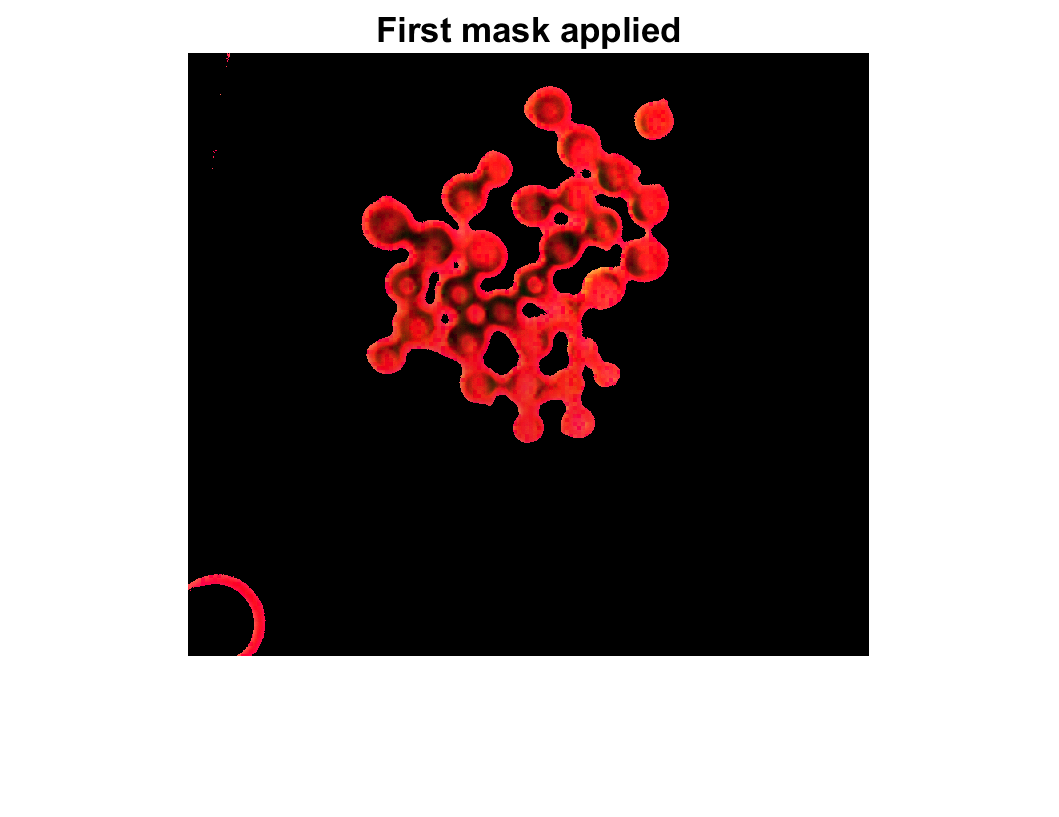

imshow(mask) 
title("First mask applied")

## Segment standard

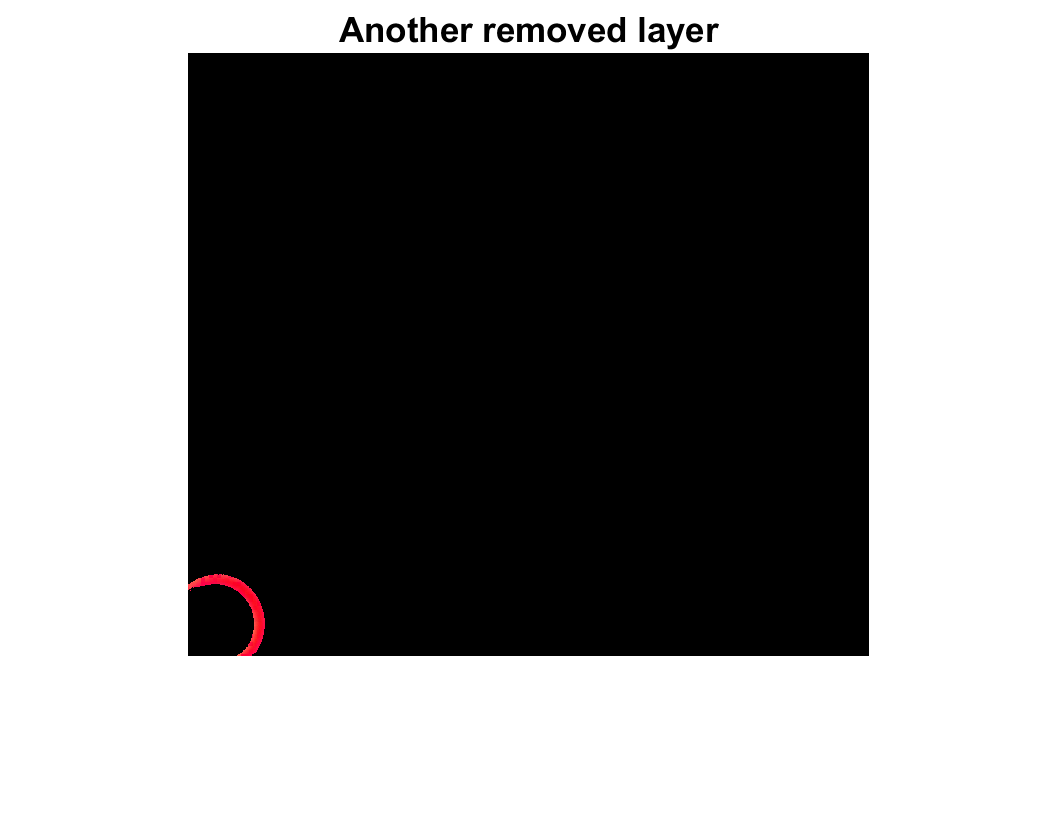

%Not stable with vertical noise, Blue mask
[bw2, maskedImg] = segStandard(mask);
circleSeg = bw2 == 0;
%title("Another portion to be subtracted")
imshow(maskedImg) 
title("Another removed layer")

## Full segmentation

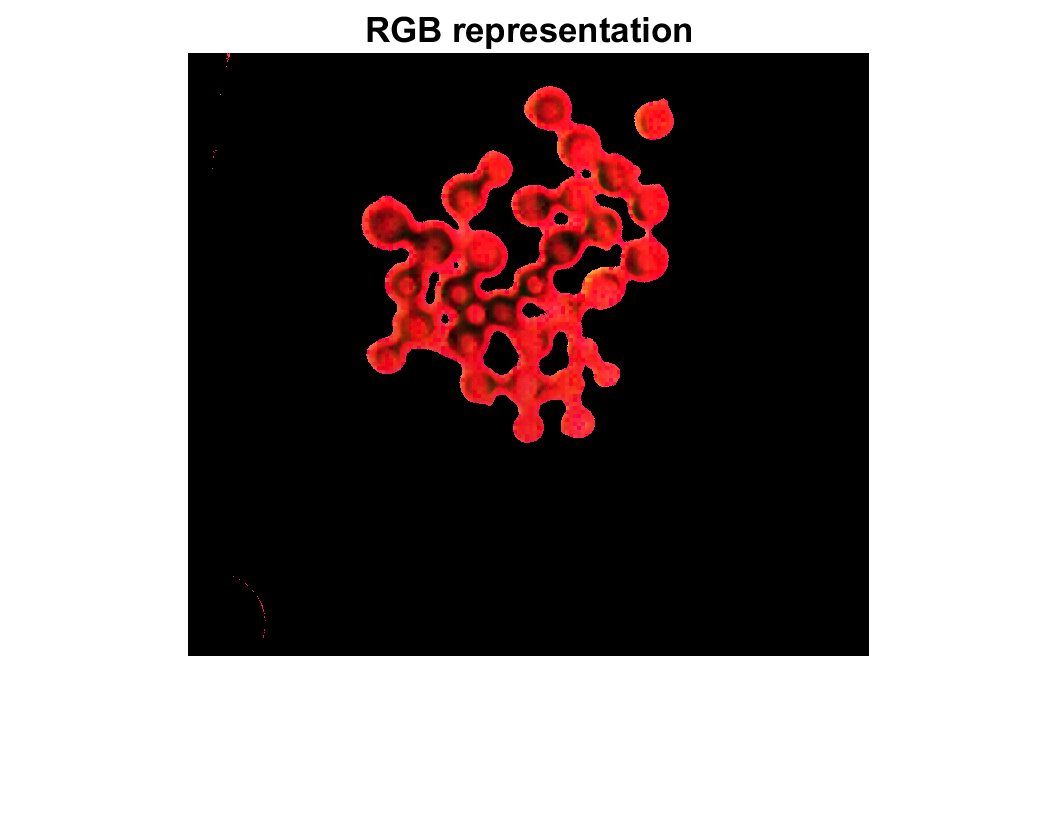

imshow(mask.*circleSeg) 
title("RGB representation") 

## Image to be analyzed

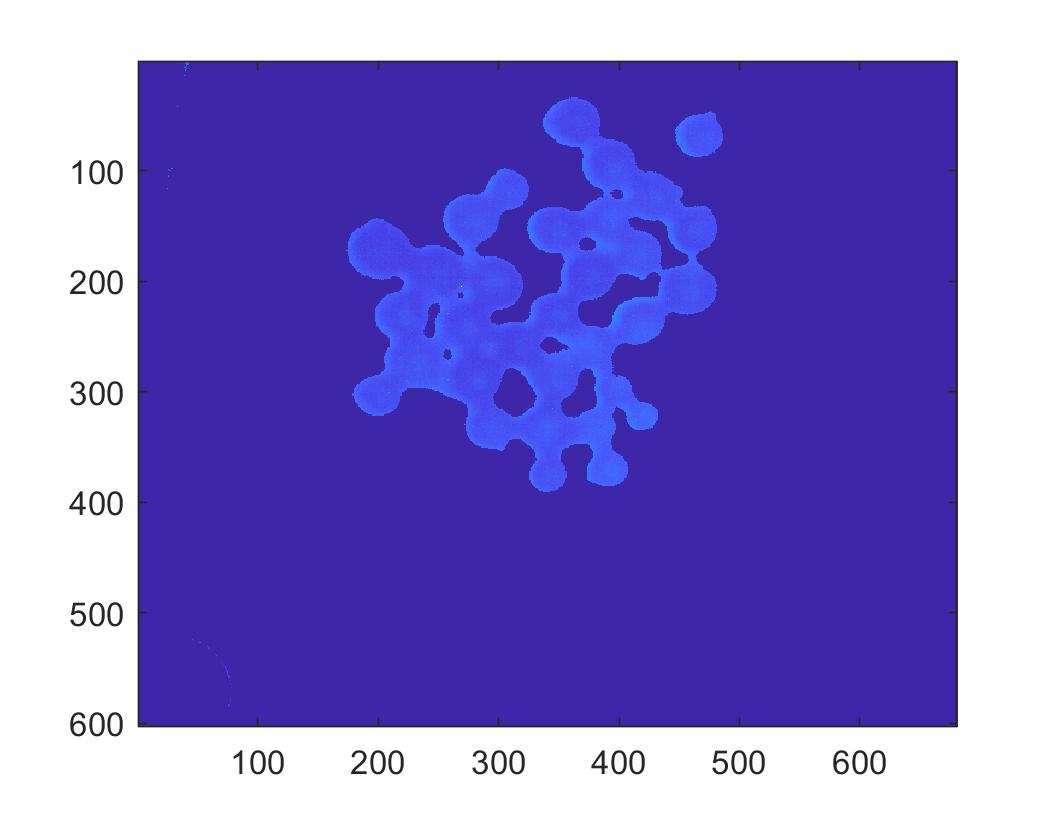

% Band 40 for representation:
% note, ID1 distinct coloration on all bands
imagesc(hCube.DataCube(:,:,64).*bw1.*circleSeg)

## Band actual image

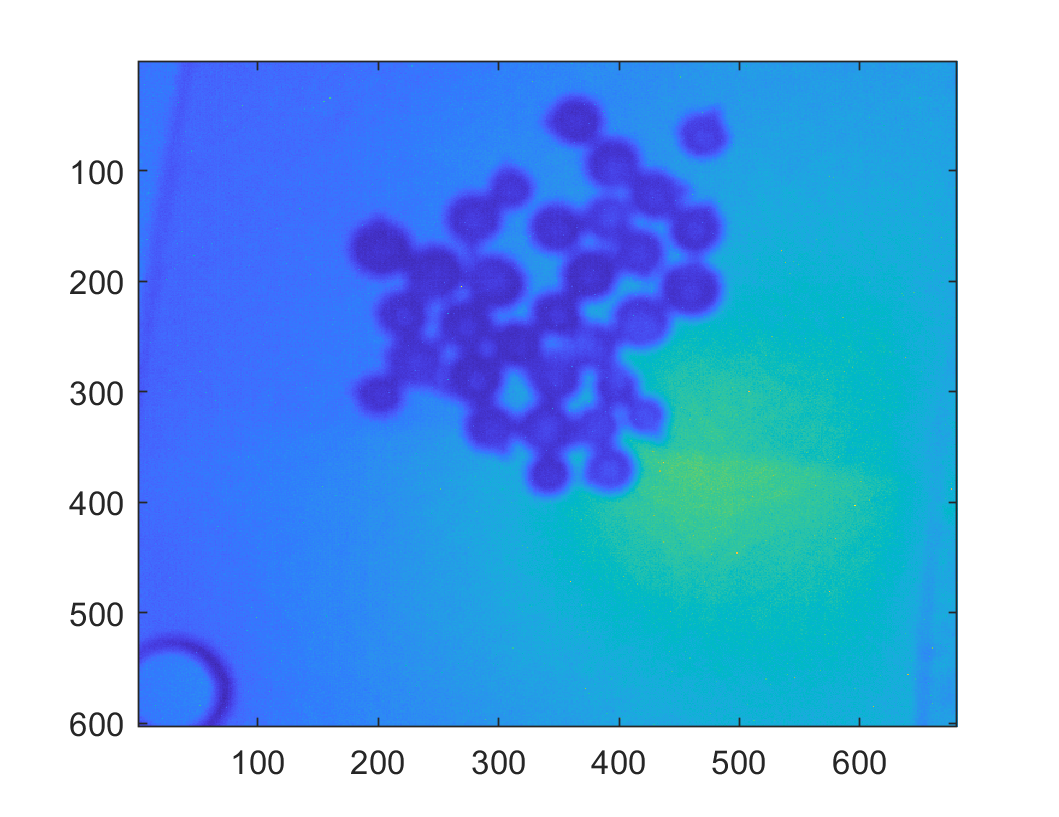

imagesc(hCube.DataCube(:,:,76))